## Question 2: Enzyme Kinetics

#### 8.1 4 equations for the rate of changes of 4 species


$$\frac{d\left\lbrack E\right\rbrack }{d\;t}=\left(k_2 +k_3 \right)\left\lbrack \textrm{ES}\right\rbrack -k_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack$$



$$\frac{d\left\lbrack S\right\rbrack }{d\;t}=k_2 \left\lbrack \textrm{ES}\right\rbrack -k_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack$$



$$\frac{d\left\lbrack \textrm{ES}\right\rbrack }{d\;t}=k_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack -\left(k_2 +k_3 \right)\left\lbrack \textrm{ES}\right\rbrack$$



$$\frac{d\left\lbrack P\right\rbrack }{d\;t}=k_3 \left\lbrack \textrm{ES}\right\rbrack$$


#### 8.2 solution of ODEs above

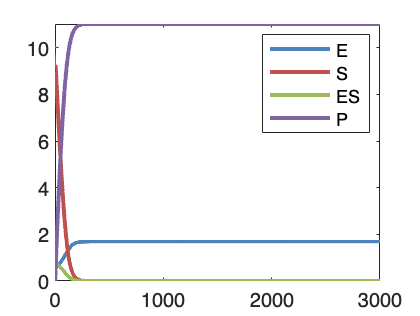

E_0 = 1;
S_0 = 10;
ES_0 = 0;
P_0 = 0;
k1 = 100;
k2 = 600;
k3 = 150;

h = 0.001; 
span = 3;
N = ceil(span/h);

for i = 1 : N-1

    K11 = fun_E(E_0(i), ES_0(i), S_0(i)); % k1 of E 
    K12 = fun_S(E_0(i), ES_0(i), S_0(i));
    K13 = fun_ES(E_0(i), ES_0(i), S_0(i));
    K14 = fun_P(ES_0(i));

    K21 = fun_E(E_0(i) + h * (1/2) * K11, ES_0(i) + h * (1/2) * K11, S_0(i) + h * (1/2) * K11); % k2 of E
    K22 = fun_S(E_0(i) + h * (1/2) * K12, ES_0(i) + h * (1/2) * K12, S_0(i) + h * (1/2) * K12);
    K23 = fun_ES(E_0(i) + h * (1/2) * K13, ES_0(i) + h * (1/2) * K13, S_0(i) + h * (1/2) * K13);
    K24 = fun_P(ES_0(i) + h * (1/2) * K14);

    K31 = fun_E(E_0(i) + h * (1/2) * K21, ES_0(i) + h * (1/2) * K21, S_0(i) + h * (1/2) * K21);
    K32 = fun_S(E_0(i) + h * (1/2) * K22, ES_0(i) + h * (1/2) * K22, S_0(i) + h * (1/2) * K22);
    K33 = fun_ES(E_0(i) + h * (1/2) * K23, ES_0(i) + h * (1/2) * K23, S_0(i) + h * (1/2) * K23);
    K34 = fun_P(ES_0(i) + h * (1/2) * K24);

    K41 = fun_E(E_0(i) + h * K31, ES_0(i) + h * K31, S_0(i) + h * K31);
    K42 = fun_S(E_0(i) + h * K32, ES_0(i) + h * K32, S_0(i) + h * K32);
    K43 = fun_ES(E_0(i) + h * K33, ES_0(i) + h * K33, S_0(i) + h * K33);
    K44 = fun_P(ES_0(i) + h * K43);

    E_0 = [E_0, E_0(i) + h * (K11 + 2 * K21 + 2 * K31 + K41)/6];
    S_0 = [S_0, S_0(i) + h * (K12 + 2 * K22 + 2 * K32 + K42)/6];
    ES_0 = [ES_0, ES_0(i) + h * (K13 + 2 * K23 + 2 * K33 + K43)/6];
    P_0 = [P_0, P_0(i) + h * (K14 + 2 * K24 + 2 * K34 + K44)/6];
end

figure;
plot(E_0, 'LineWidth', 2, 'Color', [79, 129, 189]/255);
hold on;
plot(S_0, 'LineWidth', 2, 'Color', [192, 80, 77]/255);
hold on;
plot(ES_0, 'LineWidth', 2, 'Color', [155, 187, 89]/255);
hold on;
plot(P_0, 'LineWidth', 2, 'Color', [128, 100, 162]/255);
legend('E', 'S', 'ES', 'P');

#### 8.3 plot V as f([S])

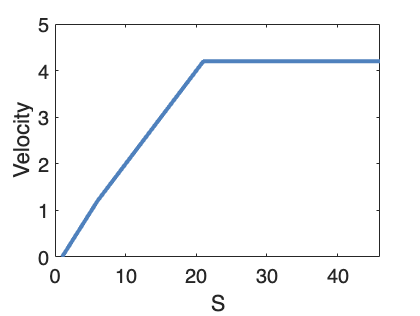

% initialization of parameters
k1 = 100;
k2 = 600;
k3 = 150;

dt = 0.001; 
tspan = 5;
loop = ceil(tspan/dt);

% initialization of variables
t = (1:loop)*dt;
E = zeros(loop,1);
S = zeros(loop,1);
ES = zeros(loop,1);
P = zeros(loop,1);
V = zeros(loop,1);

S_0 = 1 : 5 : 50;
V = zeros(size(S_0));
for j = 1:length(S_0)

    E(1) = 1;
    S(1) = S_0(j);
    ES(1) = 0;
    P(1) = 0;
    V(1) = 0;

    for i=1:loop-1 
        if S(i) > 0.0
            E(i+1) = E(i) + dt* ((k2 + k3) * ES(i) - k1 * S(i) * E(i));
            S(i+1) = S(i) + dt * (k2 * ES(i) - k1 * E(i) * S(i));
            ES(i+1) = ES(i) + dt * (k1 * E(i) * S(i) - (k2 + k3) * ES(i));
            P(i+1) = P(i) + dt * (k3 * ES(i)); 
        else
            stop = i;
            break;
        end
    end
    V(j) = (P(loop-1) - P(1)) / tspan;
end

figure;
plot(S_0, V, 'LineWidth',2, 'Color', [79, 129, 189]/255);
xlabel('S-um');
ylabel('V');
xlabel('S');
ylabel('Velocity');

From the plot, $V_m$ here is 4.2um/min.

function f_E = fun_E(E, ES, S)
    k1 = 100;
    k2 = 600;
    k3 = 150;
    f_E = (k2 + k3) * ES - k1 * E * S;
end

function f_S = fun_S(E, ES, S)
    k1 = 100;
    k2 = 600;
    k3 = 150;
    f_S = k2 * ES - k1 * E * S;
end

function f_ES = fun_ES(E, ES, S)
    k1 = 100;
    k2 = 600;
    k3 = 150;
    f_ES = k1 * E * S - (k2 + k3) * ES;
end

function f_P = fun_P(ES)
    k1 = 100;
    k2 = 600;
    k3 = 150;
    f_P = k3 * ES;
end